# The Big Picture

Below is the outline of processing chain.

Each schema corresponds to a module in the `pipeline` package *and* the corresponding database on the server.

Each node represents a class in the module *and* a table in the database.

Lines represents dependencies.

- The pipeline starts with the manual information entered in the schemas `mice` and `experiment`.

- The visual stimulus information is stored in the `vis` schema.

- The schema `preprocess` extracts traces, infers spikes, and synchronizes two-photon data to the visual stimulus.

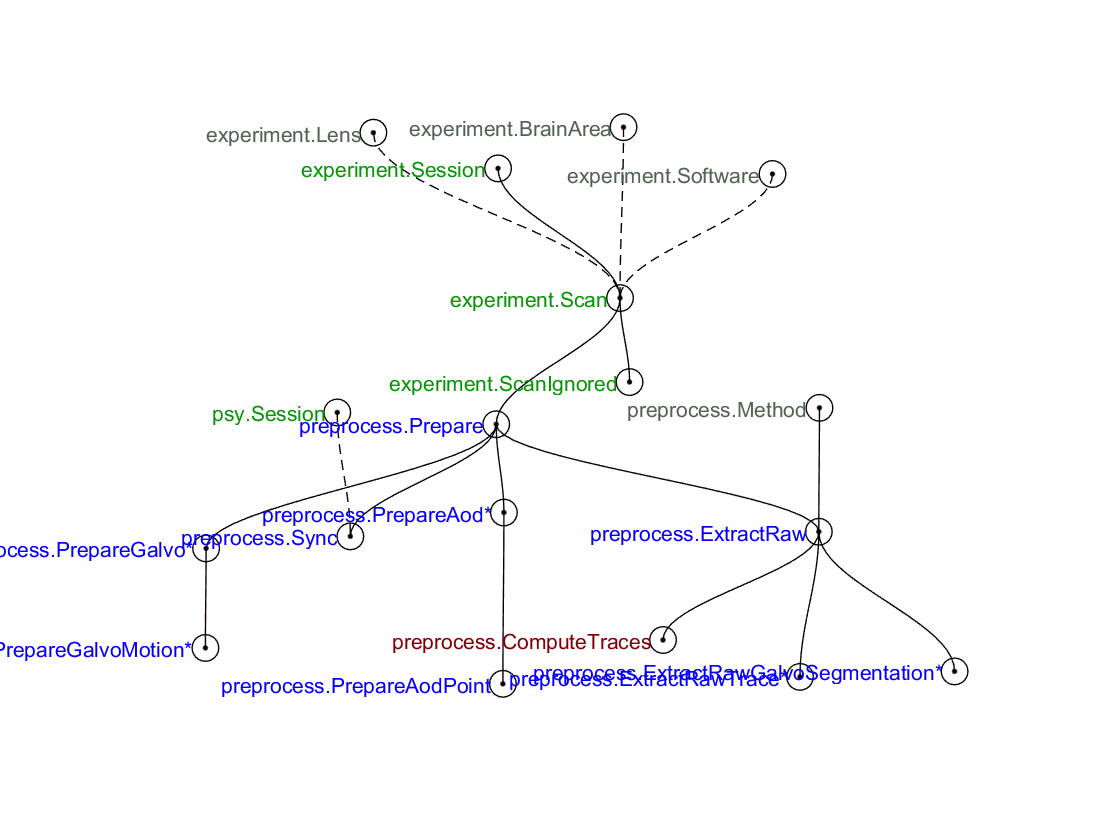

erd(preprocess.Prepare,2,2)
set(findobj(gcf,'type','text'),'fontsize',8)

That can get a bit messy, so let's just show a few specific tables:

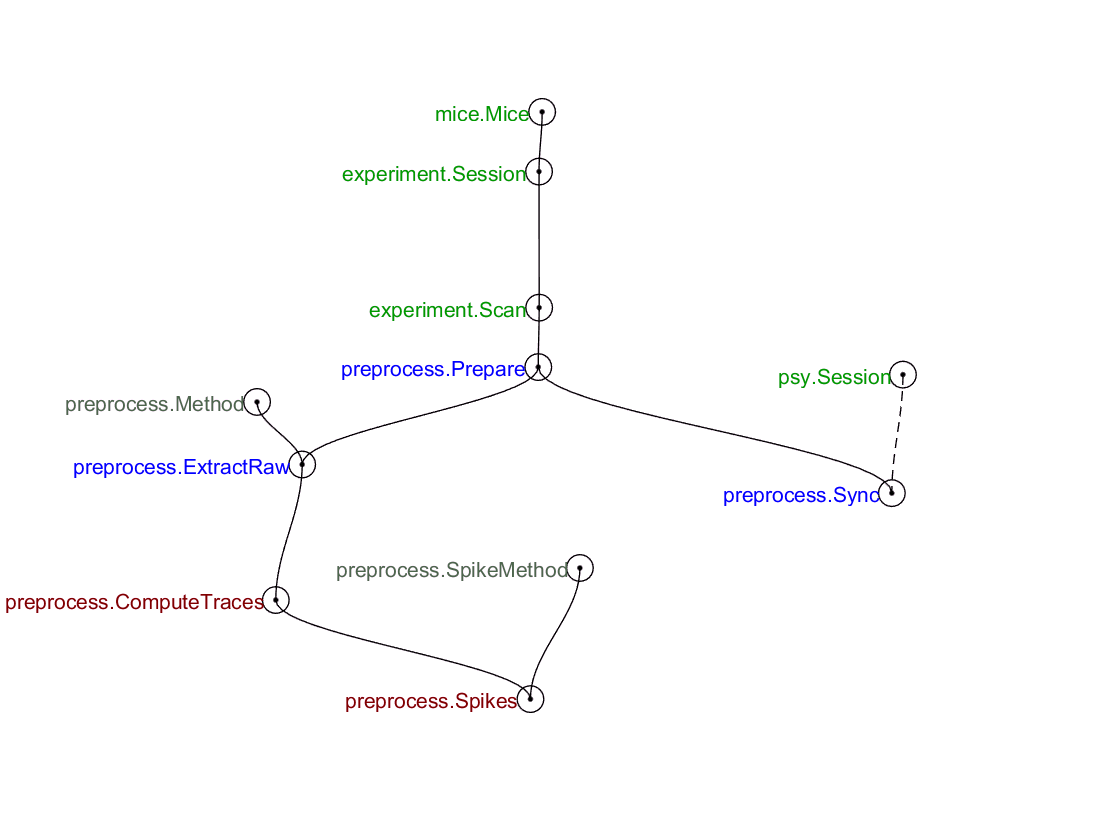

erd mice.Mice experiment.Session experiment.Scan preprocess.Prepare preprocess.Method preprocess.ExtractRaw psy.Session preprocess.Sync preprocess.ComputeTraces preprocess.SpikeMethod preprocess.Spikes
set(findobj(gcf,'type','text'),'fontsize',8)

The color code:

- Green: Manual (e.g. `experiment.Scan`) is data entered *manually* or by external software.

- Blue: Imported (e.g. `preprocess.Prepare`) is data *imported* from external files by datajoint, requires access to local drives in the lab.

- Red: Computed (e.g. `preprocess.ComputeTraces`) is *computed* by datajoint from data already in the database without access to external files, can be repopulated in the cloud.

- Grey: Lookup (e.g. `preprocess.Method`) are *lookup* tables containing general information that is not specific to any one experiment. These often contain processing settings and general knowledge.

For any table, you can see its definition (attributes, dependencies, comments) by using the `re` (reverse-engineer) method.

re(experiment.Session)

ans = %{
experiment.Session (manual) # imaging session
-> mice.Mice
session         : smallint               # session index for the mouse
---
-> experiment.Rig
-> experiment.Person
-> experiment.Anesthesia
-> experiment.PMTFilterSet
session_date                : date                          # date
scan_path                   : varchar(255)                  # file path for TIFF stacks
behavior_path               : varchar(255)                  # pupil movies, whisking, locomotion, etc.
craniotomy_notes            : varchar(4095)                 # free-text notes
session_notes               : varchar(4095)                 # free-text notes
session_ts=CURRENT_TIMESTAMP: timestamp                     # automatic
%}


For any tables or relational expressions derived from them, you may see all the attributes using the `show` method.

show(experiment.Session)

ans = %{
experiment.Session (manual) # imaging session
-> mice.Mice
session         : smallint               # session index for the mouse
---
-> experiment.Rig
-> experiment.Person
-> experiment.Anesthesia
-> experiment.PMTFilterSet
session_date                : date                          # date
scan_path                   : varchar(255)                  # file path for TIFF stacks
behavior_path               : varchar(255)                  # pupil movies, whisking, locomotion, etc.
craniotomy_notes            : varchar(4095)                 # free-text notes
session_notes               : varchar(4095)                 # free-text notes
session_ts=CURRENT_TIMESTAMP: timestamp                     # automatic
%}


Note that the attributes above the dividing line `---` comprise the *primary key*, i.e. identifying information used for matching data across different tables.

To preview the contents of a table or of a derived relational expression, simply type it at the MATLAB prompt.

experiment.Session

data = 41x1 struct array with fields:

    animal_id
    session


To fetch the contents of a table or a derived relational expression into a MATLAB stucture, use the fetch method. This returns only the primary keys. 

data = fetch(experiment.Session)

data = 41x1 struct array with fields:

    animal_id
    session
    rig
    session_date
    username
    anesthesia
    pmt_filter_set
    scan_path
    behavior_path
    craniotomy_notes
    session_notes
    session_ts


You can fetch fetch all the attributes using '*', or provide a list of specific attribute names.

data = fetch(experiment.Session,'*')